Digite agora o azimute e a elevação do ponto de vista (em graus)


Se quiser os ângulos pre-definidos introduza 0 nos dois


azimute: polar angle in the x-y plane, with positive angles indicating counterclockwise rotation of the viewpoint


elevação: angle above (positive angle) or below (negative angle) the x-y plane


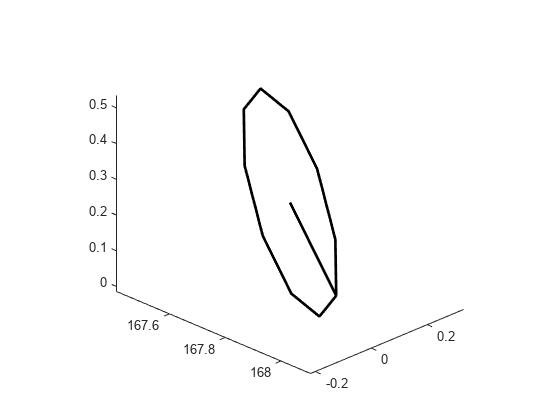

three = 3

dimension = input('Quer visualizar a mota em 2D ou 3D? (Digite "2" ou "3") - ');
if dimension == 2
    perspective = input('Que perspetiva quer? (l-lateral, f-frontal, c - de cima) - ', 's');
    if perspective == 'l'

        [two] = two_dimension(1, 3, model)
    elseif perspective == 'f'
        [two] = two_dimension(2, 3, model)
    else 
        [two] = two_dimension(2, 1, model)
    end
else
    disp('Digite agora o azimute e a elevação do ponto de vista (em graus)')
    disp('Se quiser os ângulos pre-definidos introduza 0 nos dois')
    disp('azimute: polar angle in the x-y plane, with positive angles indicating counterclockwise rotation of the viewpoint')
    disp('elevação: angle above (positive angle) or below (negative angle) the x-y plane')
    azimuth= input('azimuth = ');
    elevation = input('elevation = ');
    [three] = three_dimension(azimuth, elevation, model) 
end

function [three] = three_dimension(azimuth,elevation, model)
h1 = animatedline('LineWidth', 2);
axis equal
three = 3;
if azimuth==0 && elevation ==0
    azimuth = 45;
    elevation = 25;
end
view(azimuth,elevation)
raio = 0.3;

for k = 1:length(model.x(1,:))
    %body 1
    R_psi = [cos(model.euler(1,k)), sin(model.euler(1,k)), 0;
            -sin(model.euler(1,k)), cos(model.euler(1,k)), 0;
            0, 0, 1];
    R_phi = [1, 0, 0;
            0, cos(model.euler(2,k)), sin(model.euler(2,k));
            0, -sin(model.euler(2,k)), cos(model.euler(2,k))];
    R_theta = [cos(model.euler(3,k)), 0, sin(model.euler(3,k));
            0, 1, 0;
            -sin(model.euler(3,k)), 0, cos(model.euler(3,k))];
    R_psi_1 = R_psi';
    R_phi_1 = R_phi';
    R_theta_1 = R_theta';
    for i = 1:11
        r = R_psi_1* R_phi_1* R_theta_1*raio*[cos(36*(i-1)*pi/180);0;sin(36*(i-1)*pi/180)];
        addpoints(h1,model.x(1,k)+r(1),model.x(2,k)+r(2),model.x(3,k)+r(3));
    end
    addpoints(h1,model.x(1,k), model.x(2,k),model.x(3,k));
    
 drawnow limitrate
 clearpoints(h1)
end

end